# Chemical Reaction Engineering Basics

In chemical Reaction Engineering, we face to many ODEs. some of them have Boundary conditions and some others have Initial conditions. 

First of all, we describe the mass balance in each ideal reactors.

## 1. PFR Reactor

Consider *F* as molar flow rate, *dF *as molar flow rate difference, *dV as *volume element of reactor, and *r* as reaction rate. the mass balance will be as follows:


$$\mathrm{dF}=r\ldotp \mathrm{dV}\;\Rightarrow u\;\frac{\mathrm{dC}}{\mathrm{dz}}=r$$



$$B\ldotp C:@\;z=0\Rightarrow C=C_0$$


In a catalytic PFR, the mass balance will be:


$$\mathrm{dF}=\rho_{\mathrm{cat}\;} r^{\prime } \mathrm{dV}\Rightarrow u\;\frac{\mathrm{dc}}{\mathrm{dz}}=\rho {\;}_{\mathrm{cat}} r^{\prime \;}$$


## 2. Batch Reactor

Consider N as mole of reactant, *dN* as mole difference, *V* as reactor volume, and *dt* as time difference. The mass balance will be as follows:


$$\frac{\mathrm{dN}}{\mathrm{dt}}=r\ldotp V\;,\mathrm{if}\;V=\mathrm{cnostant}\Rightarrow \frac{\mathrm{dC}}{\mathrm{dt}}=r$$


## 3. CSTR Reactor

Consider *F* as molar flow rate, *dF *as molar flow rate difference, *dV as *volume element of reactor, and *r* as reaction rate. the mass balance will be as follows:


$$F_{\mathrm{out}} -F_{\mathrm{in}} =r\ldotp V\;,F=Q\ldotp C\Rightarrow Q\left(C_{\mathrm{out}} -C_{\mathrm{in}} \right)=r\ldotp V$$


## 4. Isothermal PFR

Consider a lliquid phase with constant volume rate in PFR. The reaction occurs using the equation below:


$$2A\to B$$


The generic mass balance equation will be:


$$u\;\frac{\mathrm{dC}}{\mathrm{dz}}=r_j \;\;\;\;,j=1,2,\ldotp \ldotp \ldotp$$


The formation rate of **B **is:


$$r_B =k\ldotp C_A^2 \;\;\;\;\;\;\;k=\left\lbrack \frac{\mathrm{vol}}{\mathrm{mol}\ldotp \min }\right\rbrack$$


And the consumption rate for **A** is:


$$r_A =-2\ldotp k\ldotp C_A^2$$


the initial condition is:


$$C_A \left(0\right)=2\;\frac{\mathrm{kmol}}{m^3 }\;\;,\;k=0\ldotp 3\;\frac{m^3 }{\mathrm{mol}\ldotp s}\;,\mathrm{Reactor}\;\mathrm{Length}\;\left(z\right)=2\ldotp 4\;m$$


We define the ODE as function in MATLAB:

% function ydot = rate1(VR, y)
% CA = y(1);
% k = 0.3;
% rate = k*CA^2;
% ydot(1) = -2.*rate/0.5;
% ydot(2) = +rate/0.5;
% end
% The function .m file is attached into the repository!

In the nect step, we have to solve the ODE using ode45 

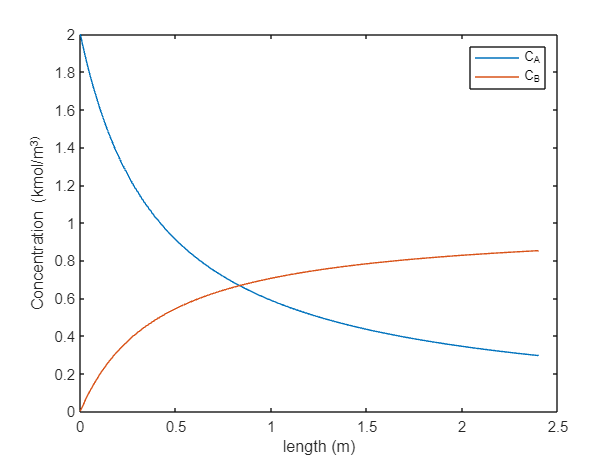

clear,clc, close
y0 = [2 0];
zspan = [0 2.4];
[z y] = ode45(@rate1, zspan, y0);
plot(z,y)
xlabel('length (m)')
ylabel('Concentration (kmol/m^3)')
legend('C_A', 'C_B')

## 5. Non-isothermal PFR

The main difference between Isothermal and Non-isothermal PFR is difference in reaction constant (k) versus Temperature and Heat Transfer inside the reactor!

Consider the oxidization of ${\mathrm{SO}}_2$ from ${\mathrm{SO}}_3$. The reaction rate and heat balance are as follows:


$$\frac{\mathrm{dX}}{\mathrm{dz}}=-50\ldotp R^{\prime \;}$$



$$\frac{\mathrm{dT}}{\mathrm{dz}}=-4\ldotp 1\;\left(T-T_{\mathrm{surr}} \right)+1\ldotp 02\times {10}^4 R^{\prime \;}$$



$$R^{\prime } =\frac{X{\left\lbrack \left(1-0\ldotp 167\left(1-X\right)\right)\right\rbrack }^2 -2\ldotp 2\left(1-X\right)}{{k_{\mathrm{eq}} \ldotp \left\lbrack k_1 +k_{2\;} \left(1-X\right)\right\rbrack }^2 }$$



$$\begin{array}{l}
\ln \left(k_1 \right)=-14\ldotp 96+\frac{11070}{T}\\
\ln \left(k_2 \right)=-1\ldotp 331+\frac{2331}{T}\\
T_{\mathrm{surr}} =673\ldotp 2\;K\;,T_0 =673\ldotp 2\;K,X\left(0\right)=1
\end{array}$$



$$y\left(1\right)=X\;,y\left(2\right)=T$$


We define the mass and heat balance as function:

% function ydot=rateSO2(z,y)
% X=y(1);
% T=y(2);
% k1=exp(-14.96+11070/T);
% k2=exp(-1.331+2331/T);
% Keq=exp(-11.02+11570/T);
% term1=X*sqrt(1-0.167*(1-X));
% term2=2.2*(1-X)/Keq;
% denom=(k1+k2*(1-X))^2;
% rate=(term1-term2)/denom;
% ydot(1)=-50*rate;
% ydot(2)=-4.1*(T-673.2)+1.02e4*rate;
% ydot=ydot';
% end
% The function .m file is attached into the repository!

In the nect step, we have to solve the ODEs using ode45 :

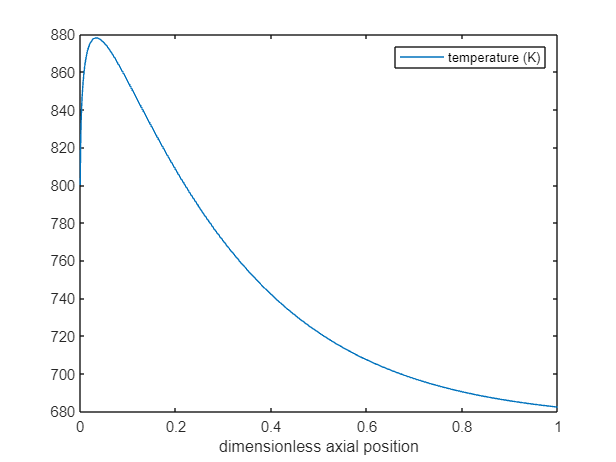

% dimensionless initial conditions
y0=[1 800];
% integration range
zspan=[0 1];
% the solver
[z y]=ode45(@rateSO2,zspan,y0);
% plot the result
plot(z,y(:,2))
xlabel('dimensionless axial position')
legend('temperature (K)')

## 6. Chemical Reactors with mass transfer limitations (Catalytic Reactors)

According to the reaction in Section 5, If reactant concentration on the surface equal to $C_s$, the $k_{\mathrm{mol}}$ will be defined as every component over catalyst surface:


$$u\;\frac{{\mathrm{dC}}_A }{\mathrm{dz}}=-2k_s C_{A_s }^2 \;,u\;\frac{{\mathrm{dC}}_B }{\mathrm{dz}}=-2k_s C_{A_s }^2 \;\;,u\;\frac{{\mathrm{dC}}_C }{\mathrm{dz}}=0$$


To solve the equations above, we have to set a mass balance for relating mass transfer in catalyst surface to reaction rate. Consider $k_m$ as mass transfer coefficient, $a$ as special area, and $k_s$ as reaction rate constant. Thus:


$$k_m \;a\;\left(C_A -C_{A,s} \right)=k_s C_{A,s}^2$$


In this step, we have to define mass balances (ODEs) as a function:

% function y=mass_rxn(CAs,CA)
% global k km
% y=km*(CA-CAs)-k*CAs*CAs;
% end
% The function .m file is attached into the repository!

In addition, we have to define another function to describe mass transfer on the catalyst surface, slove the equation and find $C_{A_s }$:

% function ydot=rate1_mass(VR,y)
% global k vel km
% % y(1) is CA, y(2) is CB, y(3) is CC
% CA=y(1);
% % mass transfer problem
% OPTIONS=[]
% CAguess=CA;
% CAs=fzero(@mass_rxn,CAguess,OPTIONS,CA);
% rate=k*CAs*CAs;
% ydot(1)=-2.*rate/vel;
% ydot(2)=+rate/vel;
% ydot(3)=0.;
% ydot=ydot';
% end
% The function .m file is attached into the repository!

In the nect step, we have to solve the ODEs using ode45 :

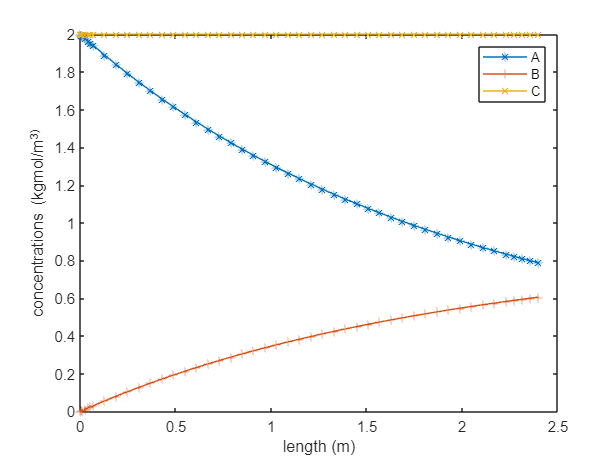

global k vel km
k=0.3; vel=0.5; km=0.2;
% the initial conditions
y0=[2 0 2];
% the total volume of the reactor
zspan=[0 2.4];
% the ode solver
[z y]=ode45(@rate1_mass,zspan,y0);
% plot the result
plot(z,y(:,1),'*-',z,y(:,2),'+-',z,y(:,3),'x-')
xlabel('length (m)')
ylabel('concentrations (kgmol/m^3)')
legend('A', 'B', 'C')

## 7. Non-isothermal CSTR reactors

With respect to mass balance in CSTR reactors, we have to define heat balance as follows:


$$\frac{Q}{V_R }\left(1-C\right)=C\ldotp \exp \left\lbrack \gamma \left(1-\frac{1}{T}\right)\right\rbrack \Rightarrow \frac{Q}{V}\left(1-T\right)=-\beta \;C\ldotp \exp \left\lbrack \gamma \;\left(1-\frac{1}{T}\right)\right\rbrack \;\left(\mathrm{for}\;\mathrm{adiabatic}\;\mathrm{reactors}\right)$$


In adiabatic condition we have:


$$\beta \;\left(1-C\right)\left(1-T\right)=0\Rightarrow T=1+\beta \;\left(1-C\right)$$


Now we can rearrange the heat balance equation:


$$-\frac{Q}{V}\left(1-C\right)=C\;\exp \left\lbrack \gamma \;\left(1-\frac{1}{1+\beta -\beta \;C}\right)\right\rbrack$$


The equations above has been defined as a functions in MATLAB.

% function fn=rate_T(c)
% global beta gamma flowvol
% T=1+beta*(1-c)
% rate=c*exp(gamma*(1-1/T))
% fn=flowvol*(1-c)-rate
% end
% The function .m file is attached into the repository!

And,

% function fn=rate_T2(y)
% global beta gamma flowvol
% c=y(1);
% T=y(2);
% rate=c*exp(gamma*(1-1/T));
% fn(1)=flowvol*(1-c)-rate;
% fn(2)=flowvol*(1-T)+beta*rate;
% end
% The function .m file is attached into the repository!

## 8. Transient CSTR reactors

The main point of transient CSTR reactors is the required time to reach stability in reactor. Using the heat and mass balance, it is described as follows:


$$\begin{array}{l}
V\;\frac{{\mathrm{dC}}^{\prime } }{{\mathrm{dt}}^{\prime } }=Q\left(C^{\prime } -C_{\mathrm{in}}^{\prime } \right)-{\mathrm{Vk}}_0 C^{\prime } \ldotp \exp \left(-\frac{E}{\mathrm{RT}}\right)\\
\left\lbrack \phi \;{\left(\rho \;C_p \right)}_f +\left(1-\phi \;\right){\left(\rho \;C_p \right)}_s \right\rbrack \frac{{\mathrm{dT}}^{\prime } }{{\mathrm{dt}}^{\prime } }={\left(-\rho \;C_p \right)}_f Q\left(T-{T_{\mathrm{in}} }^{\prime } \right)+\left(-\Delta \;H_{\mathrm{rxn}} \right)+{\mathrm{Vk}}_0 C^{\prime } \ldotp \exp \left(-\frac{E}{\mathrm{RT}}\right)
\end{array}$$


Which $V$ represents as reactor volume, $Q$ as volume flow rate, $C$ as concentration, $t$ as time, $k_0$ as reaction rate constants, $E$ as activation energy, $\phi \;$ as void fraction, $\rho \;$ as density,  $C_p$ as specific heat capacity, $\Delta H$ as reaction heat, and ***{s,f}*** indexes as solid and fliud phase.

In this step, we have to convert the equation above into dimensionless form:


$$\begin{array}{l}
\frac{\mathrm{dC}}{\mathrm{dT}}=\left\lbrack \left(1-C\right)-C\right\rbrack \ldotp \mathrm{Da}\ldotp \exp \left\lbrack \gamma \;\left(1-\frac{1}{T}\right)\right\rbrack \\
\mathrm{Le}\;\frac{\mathrm{dT}}{\mathrm{dt}}=\left(1-T\right)+\beta \;\ldotp C\ldotp \mathrm{Da}\ldotp \exp \left\lbrack \gamma \;\left(1-\frac{1}{T}\right)\right\rbrack 
\end{array}$$


Which Da represents [damkohler number](https://en.wikipedia.org/wiki/Damk%C3%B6hler_numbers), and Le represents [Lewis number](https://en.wikipedia.org/wiki/Lewis_number). 

Let's solve an ordinary problems with this context. for the dimnsionless heat balance, we define a function in MATLAB:

% function ydot=rate_limit(t,y)
% global beta gamma Damk Lewis Tin
% c=y(1);
% T=y(2);
% rate=c*Damk*exp(gamma*(1-1/T));
% ydot(1)=1-c-rate;
% ydot(2)=Tin-T+beta*rate;
% ydot(2)=ydot(2)/Lewis;
% ydot=ydot';
% end